## Lec 8

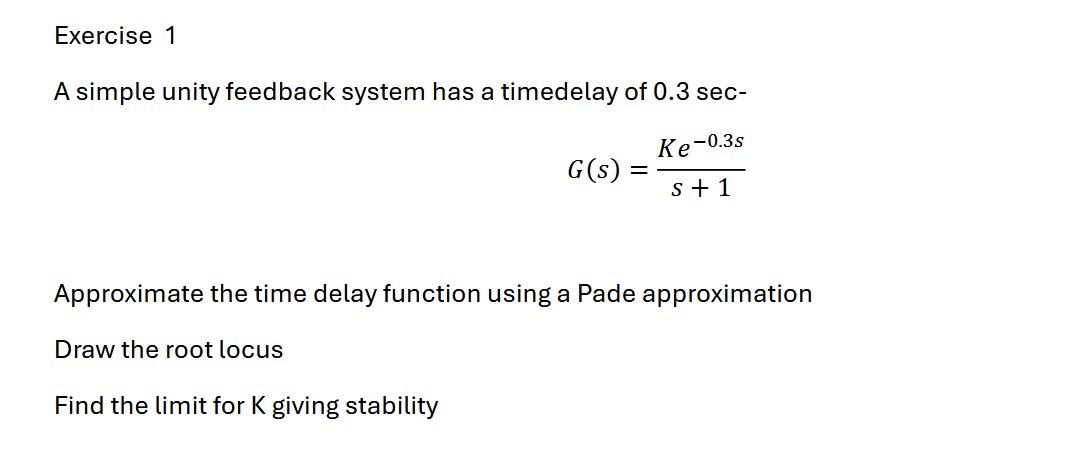

Pade approximation: (m,n)-order pade approximation: $e^{-T_d s} \approx \frac{\sum_{k=0}^m \frac{{\left(-T_d s\right)}^k }{k!}\;}{\sum_{k=0}^n \frac{{\left(T_d s\right)}^k }{k!}\;}$ vi vælger (1,1) orden for $T_d =0\ldotp 3s$ som indsættes: $e^{-0\ldotp 3s} \approx \frac{1-0\ldotp 15s}{1+0\ldotp 15s}$

close all
clear
syms K
s = tf('s');
G = (((1-0.15*s)/(1+0.15*s))/(s+1));
rlocus(G); % Ved at se på rootlocus der kan man få et stabilt system for K =< 7.

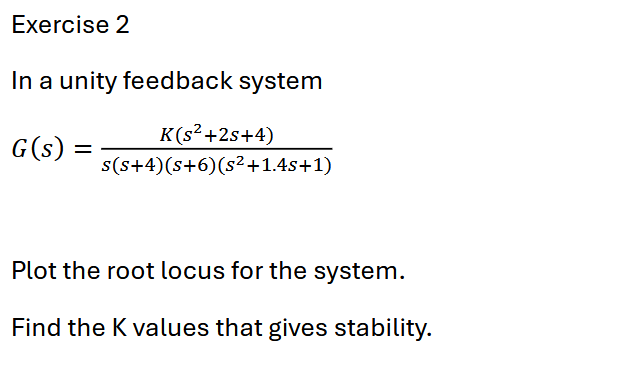

close all
clear
s = tf('s');
G = (s^2+2*s+4)/(s*(s+4)*(s+6)*(s^2+1.4*s+1));
rlocus(G); % Så K mindre end 15.6, K større end 70, K mindre end 165 disse områder giver stabilitet.

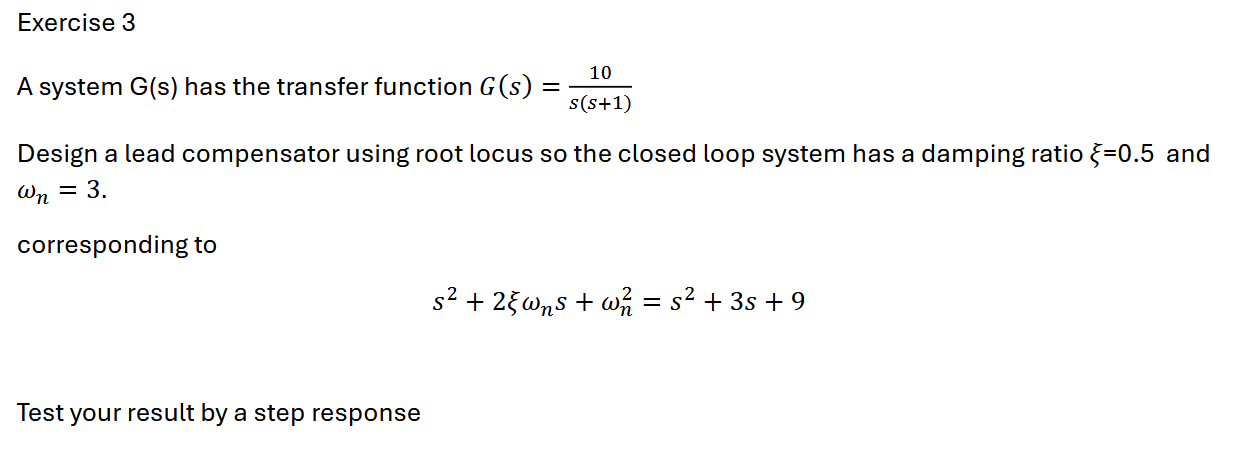

Find først pole lokation. Grundet det andet orden så kan man benytte: $s_{1,2} =-\zeta \omega_n \pm j\omega_n \sqrt{1-\zeta^2 }$ Herefter sæt ind det er blevet givet:


$$s_{1,2} =-0\ldotp 5\cdot 3\pm \mathrm{j3}\sqrt{1-{0\ldotp 5}^2 }=-1\ldotp 5\pm \mathrm{j2}\ldotp 598$$


close all
clear
syms s
G = 10/(s*(s+1));
D = (s)/(s + (2));
expand(G*D)

$$ans = \frac{10}{s^{2}+3\,s+2}$$